% Example 7.5
% 용접 헤드 제어
% K가 2개

% beta = 0
% alpha 구하는 과정
clear all
sys = tf([1],[1 2 0])

sys =
 
      1
  ---------
  s^2 + 2 s
 
연속시간 전달 함수입니다.
모델 속성


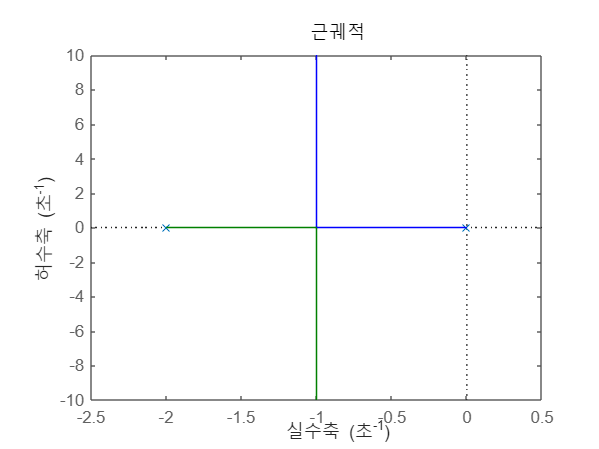

figure();
rlocus(sys);
axis([-2.5 0.5 -10 10]);

% alpha = 20
% beta 구하는 과정
clear all
sys = tf([1 0],[1 2 20])

sys =
 
        s
  --------------
  s^2 + 2 s + 20
 
연속시간 전달 함수입니다.
모델 속성


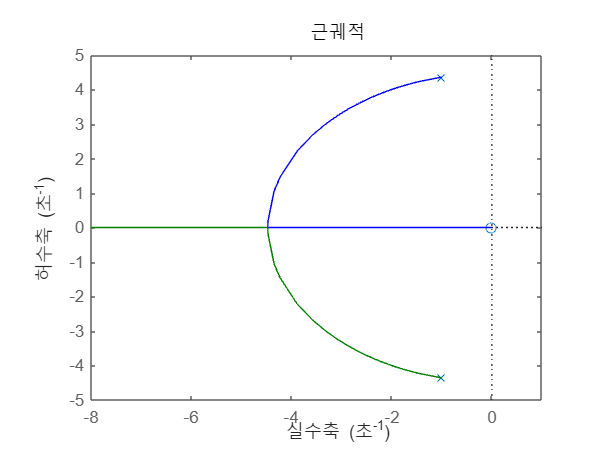

figure();
rlocus(sys);
axis([-8 1 -5 5]);

% sensitivity 확인
clear all
sys = tf([1 0],[1 2 20])

sys =
 
        s
  --------------
  s^2 + 2 s + 20
 
연속시간 전달 함수입니다.
모델 속성


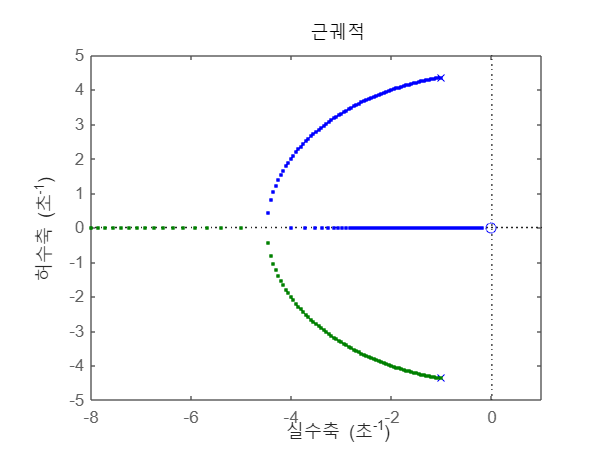

figure();
rlocus(sys, ".", 0:0.1:100);
axis([-8 1 -5 5]);